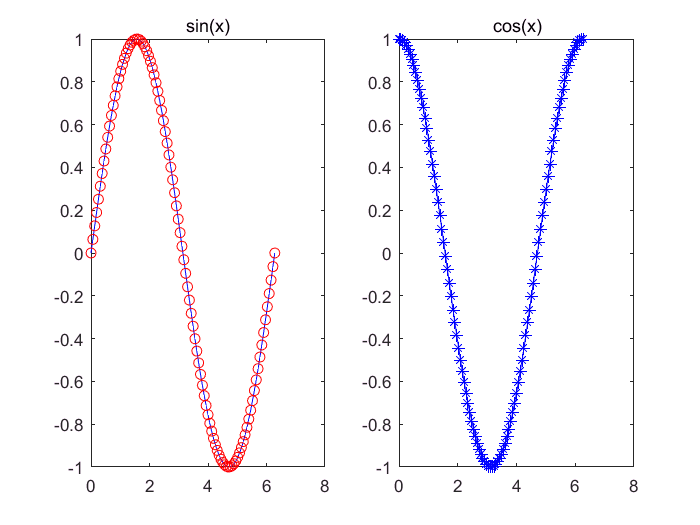

subplot(1,2,1);
x = linspace(0,2*pi);
y1 = sin(x);
plot(x,y1,'b')
hold on
title('sin(x)');
scatter(x,y1,'r','o')
hold off

subplot(1,2,2); 
y2 = cos(x);
plot(x,y2,'b')
title('cos(x)');
hold on
scatter(x,y2,'b','*')
hold off

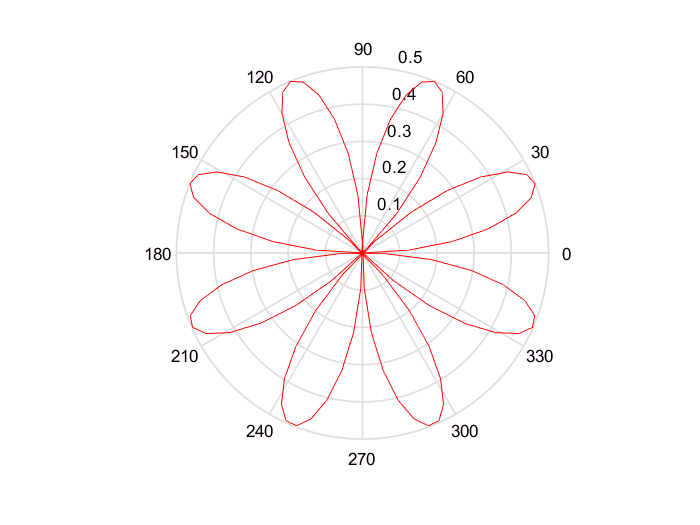

clf;
t = linspace(0,2*pi);
r = sin(2*t).*cos(2*t);
polar(t,r,'r');

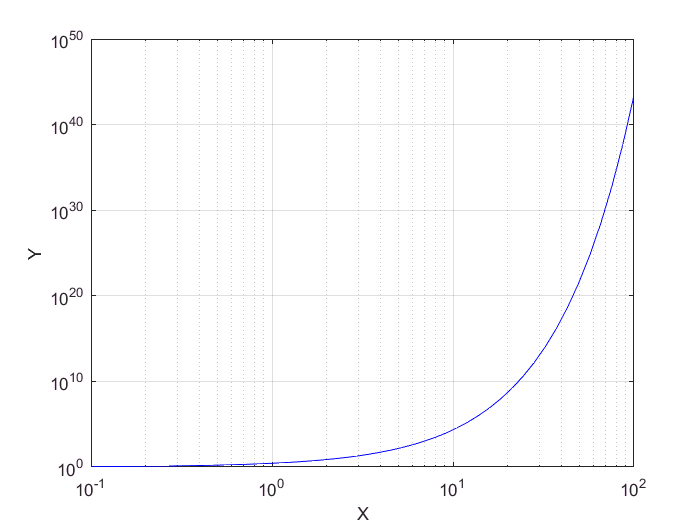

x = logspace(-1,2);
y = exp(x);
loglog(x,y,'b')
grid on
xlabel('X');
ylabel('Y');

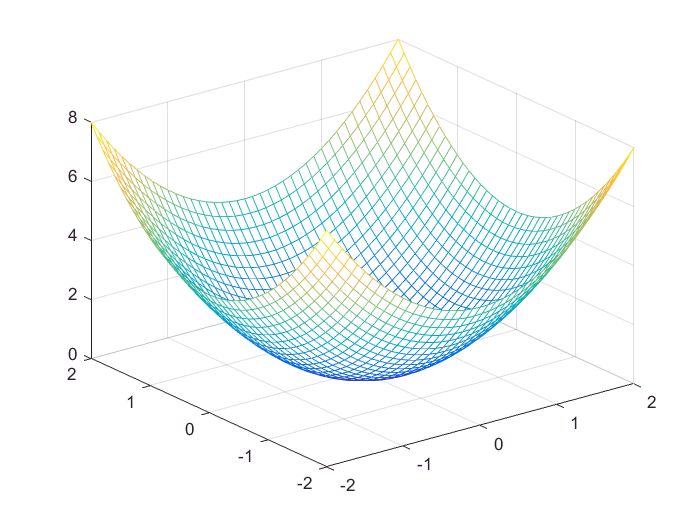

clf;
[x,y]=meshgrid(-2:0.1:2, -2:0.1:2);
z=x.^2+y.^2;
mesh(x,y,z)

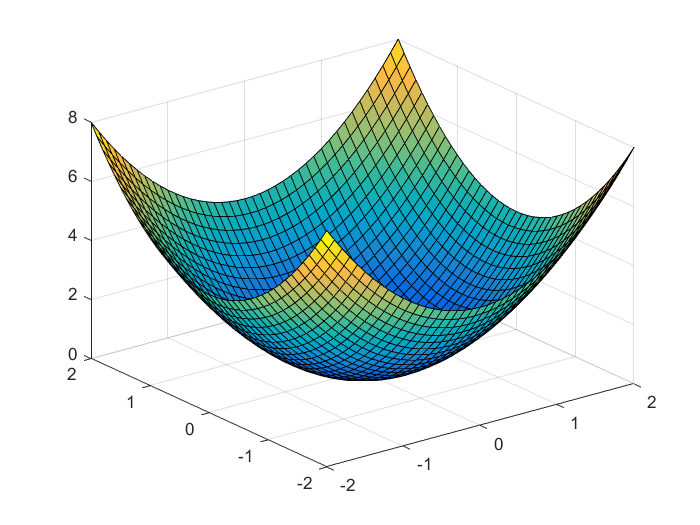

surf(x,y,z)

clf;
a=[2 -6 3 0 7];
p=poly2sym(a)

$$p = 2\,x^{4}-6\,x^{3}+3\,x^{2}+7$$

roots(a)

ans =    1.9322 + 0.4714i
   1.9322 - 0.4714i
  -0.4322 + 0.8355i
  -0.4322 - 0.8355i


polyval(a,1)

ans = 6

clf;
x=[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
y=[-0.232  0.647  1.877  3.565  5.134  7.443  9.221 10.011  11.678  12.566   13.788];
p1=polyfit(x,y,2)

p1 =    -1.8669   16.7904   -0.8601


p2=polyfit(x,y,3)

p2 =   -13.9883   19.1156    8.7890   -0.3565


scatter(x,y);
hold on ;
f1=poly2sym(p1);
y1=polyval(p1,x)

y1 =    -0.8601    0.8002    2.4233    4.0090    5.5573    7.0683    8.5420    9.9783   11.3773   12.7390   14.0633


f2=poly2sym(p2);
y2=polyval(p2,x)

y2 =    -0.3565    0.6995    2.0540    3.6229    5.3223    7.0683    8.7770   10.3644   11.7466   12.8397   13.5597


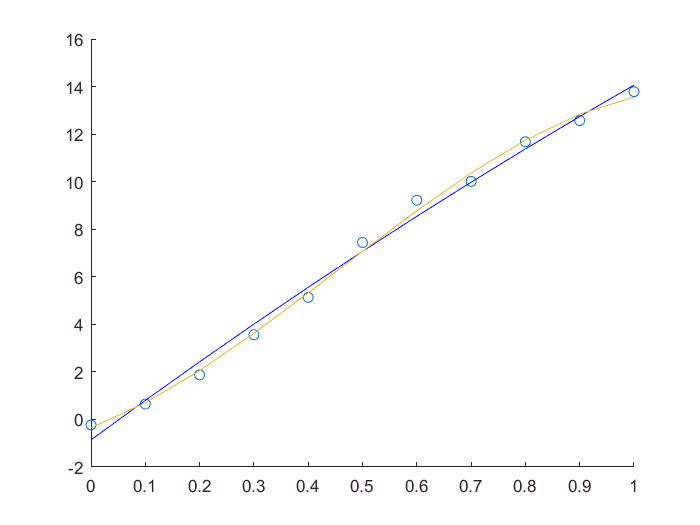

plot(x,y1,'Color','b');
plot(x,y2);


%数理统计
T = readtable('体测成绩.xls');
T1=T(:,{'class','height'});
tongji = grpstats(T1, 'class' ,{'mean','max','min','std'})

tongji =                 class       GroupCount    mean_height    max_height    min_height    std_height
              __________    __________    ___________    __________    __________    __________

    210411    2.1041e+05    15            168.71         181.8           158         7.8073    
    210412    2.1041e+05    11            163.99         185.7         153.8         9.2754    


T2 = T(:,{'height','weight','VC','score1','score2','score3'});
t2 = table2array(T2)

t2 =    1.0e+03 *

    0.1698    0.0487    3.3270    0.0690    0.0720    0.0600
    0.1740    0.0715    2.8050    0.0840    0.0940    0.0750
    0.1619    0.0521    3.6250    0.0840    0.0720    0.0600
    0.1783    0.0538    3.6780    0.0600    0.1000    0.0500
    0.1599    0.0552    3.0070    0.0630    0.1000    0.0780
    0.1621    0.0577    2.8000    0.0600    0.0870    0.0780
    0.1712    0.0722    1.6090    0.0960    0.0720    0.0630
    0.1621    0.0483    3.0590    0.0750    0.1000    0.0600
    0.1653    0.0627    4.3110    0.0720    0.0920    0.0600
    0.1818    0.0935    7.3590    0.0630    0.0600    0.0630


corrcoef(t2)

ans =     1.0000    0.7133    0.5790   -0.3298   -0.4539   -0.2985
    0.7133    1.0000    0.5891   -0.0958   -0.4940   -0.0273
    0.5790    0.5891    1.0000   -0.4514   -0.3258   -0.0414
   -0.3298   -0.0958   -0.4514    1.0000    0.1396    0.3301
   -0.4539   -0.4940   -0.3258    0.1396    1.0000    0.3582
   -0.2985   -0.0273   -0.0414    0.3301    0.3582    1.0000


%正态分布参数估计
x = [15.14,14.81,15.11,15.26,15.08,15.17,15.12,14.95,15.05,14.87];
[mmuhat,sigmahat,muci,sigmaci] = normfit(x,0.1)

mmuhat = 15.0560

sigmahat = 0.1397

muci =    14.9750
   15.1370


sigmaci =     0.1019
    0.2298
